%根据Monte Carlo方法随机生成n个单元位置，
%计算邻接矩阵AM对应结构生成的化学概率
clc;
clear all;

n=5;
%AM为考察互锁结构的邻接矩阵
AM=ones(n);

for i=1:n
    AM(i,i)=0;
end

AM

AM =      0     1     1     1     1
     1     0     1     1     1
     1     1     0     1     1
     1     1     1     0     1
     1     1     1     1     0



A=[];
B=[];

for trial=1:5

    P1=[];
    P2=[];
    
    for l=5:0.1:6
    L=(n-1)*l;
    
    count1=0;
    count2=0;
    
    n_mer=0;
    config=0;
    
        %通过蒙特卡洛方法计算生成AM互锁结构的化学概率
        for count=1:10^8
            density=[];
            a=-L;
            b=L;
        
            %R1为所有单体左端盖子位置的集合
            %R2为所有单体右端盖子位置的集合
            R1=[0];
            R2=[l];
            for s=2:n
                r=a+(b-a)*rand(1,1);
                R1=[R1 r];
                R2=[R2 r+l];
            end
                
            start=sort(R1);
                
            signal=1;
            
            %判断随机排列的n个单体是否生成n聚互锁结构(如是,signal=1)
            for i=2:size(start,2)
                if start(i)<=start(i-1)+l
                    signal=signal*1;
                else
                    signal=signal*0;
                    break
                end
            end
            
            if signal==1
        
                Position=sort([R1 R2]);
                
                %根据各个盖子的位置计算相应n聚体的概率密度函数Ptotal
                for i=2:length(Position)
                    density=[density,P(Position(i)-Position(i-1))];
                end
                
                density;
                Ptotal=prod(density);
                
                %计算所有n具体总的相体积(n_mer),以及满足AM互锁结构的相体积(config)
                n_mer=n_mer+Ptotal;
                count1=count1+1;
                if cat_config(AM,start,l)==1
                    config=config+Ptotal;
                    count2=count2+1;
                end
            end
        end
    
    count1;
    n_mer;
    count2;
    config;
    probability=config/n_mer
    P1=[P1,probability];
    
    end

    A=[A;P1];

end

probability = 6.1420e-09

probability = 2.1928e-08

probability = 3.9164e-04

probability = 0.0014

probability = 0.0428

probability = 0.1030

probability = 0.1928

probability = 0.4027

probability = 0.4904

probability = 0.5317

probability = 0.4968

probability = 7.6871e-09

probability = 6.3262e-06

probability = 7.0639e-04

probability = 0.0012

probability = 0.0706

probability = 0.3042

probability = 0.2555

probability = 0.3760

probability = 0.4997

probability = 0.4925

probability = 0.5113

probability = 5.3310e-09

probability = 6.5652e-06

probability = 6.2732e-05

probability = 0.0214

probability = 0.1517

probability = 0.3290

probability = 0.2818

probability = 0.4327

probability = 0.5095

probability = 0.4632

probability = 0.3748

probability = 1.1414e-11

probability = 3.4170e-06

probability = 3.4524e-04

probability = 0.0031

probability = 0.0458

probability = 0.0565

probability = 0.3731

probability = 0.5045

probability = 0.5172

probability = 0.4262

probability = 0.4634

probability = 4.4244e-09

probability = 1.0336e-07

probability = 7.4309e-04

probability = 0.0098

probability = 0.0341

probability = 0.3470

probability = 0.4606

probability = 0.3929

probability = 0.4583

probability = 0.5665

probability = 0.4409


P_MC=mean(A);
err1=std(A);

X=5:0.1:6

X =     5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000    6.0000


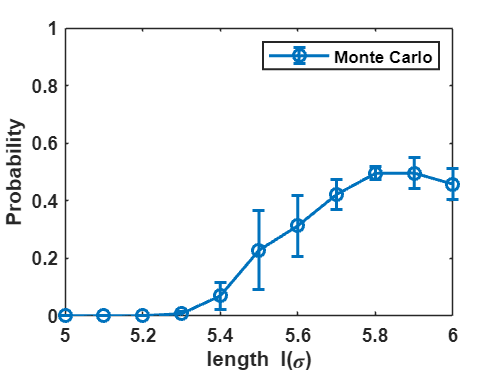


errorbar(X,P_MC,err1,'-o',LineWidth=1.5)

ylim([0 1]);

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('length l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('Probability','FontName','arial','FontWeight','bold');
legend( ['Monte Carlo'],'Location','northeast','FontName','arial');

function BM=border(n)
%给定阶数n，生成对映的边界矩阵BM（border matrix）
%该矩阵对映了邻接矩阵AM上三角矩阵中处于0和1边界中1的位置
   BM=zeros(n);

if n==2
   BM(:,:,end+1)=[0 1;0 0];
end

if n>2
   A=border(n-1);
   C=zeros(1,n);
   for i=1:size(A,3)
        B=[zeros(n-1,1),A(:,:,i)];
        for j=2:find(B(1,:)==1)
            C(1,j)=1;
            BM(:,:,end+1)=[C;B];
            C=zeros(1,n);
        end
   end
end
BM(:,:,1)=[];
end
%-------------------------------------------------
function AM=adj_mat(n)
%根据边界矩阵BM，写出n阶所有邻接矩阵AM
BM=border(n);
AM=zeros(n);

for i=1:size(BM,3)
    A=BM(:,:,i);
    for j=1:n-1
        for k=j+1:find(A(j,:)==1)
            A(j,k)=1;
        end
    end
    A=A+A';
    AM(:,:,end+1)=A;
end
AM(:,:,1)=[];
end



%-------------------------------------------------
function signal=cat_config(AM,seq,l)
%根据邻接矩阵AM，判断随机给出单元位置坐标的数列是否属于该构型
ran=sort(seq);

signal=1;

for i=1:size(AM,1)
    pos1=find(AM(i,:)==1);
    pos2=find(AM(i,:)==0);
    pos2(pos2==i)=[];
    for j=1:length(pos1)
        if abs(ran(i)-ran(pos1(j)))<=l
            signal=signal*1;
        else
            signal=signal*0;
            break
        end
    end

    for j=1:length(pos2)
        if abs(ran(i)-ran(pos2(j)))>l
            signal=signal*1;
        else
            signal=signal*0;
            break
        end
    end
end

signal;
%signal=1则属于该构型，反之不属于
end


%-------------------------------------------------
function a= E(r) %定义特定的势能函数E(r)
    e=4120;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

%-------------------------------------------------
function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end







